Code to create the background banner for the promotional Instagram post and Facebook event page.

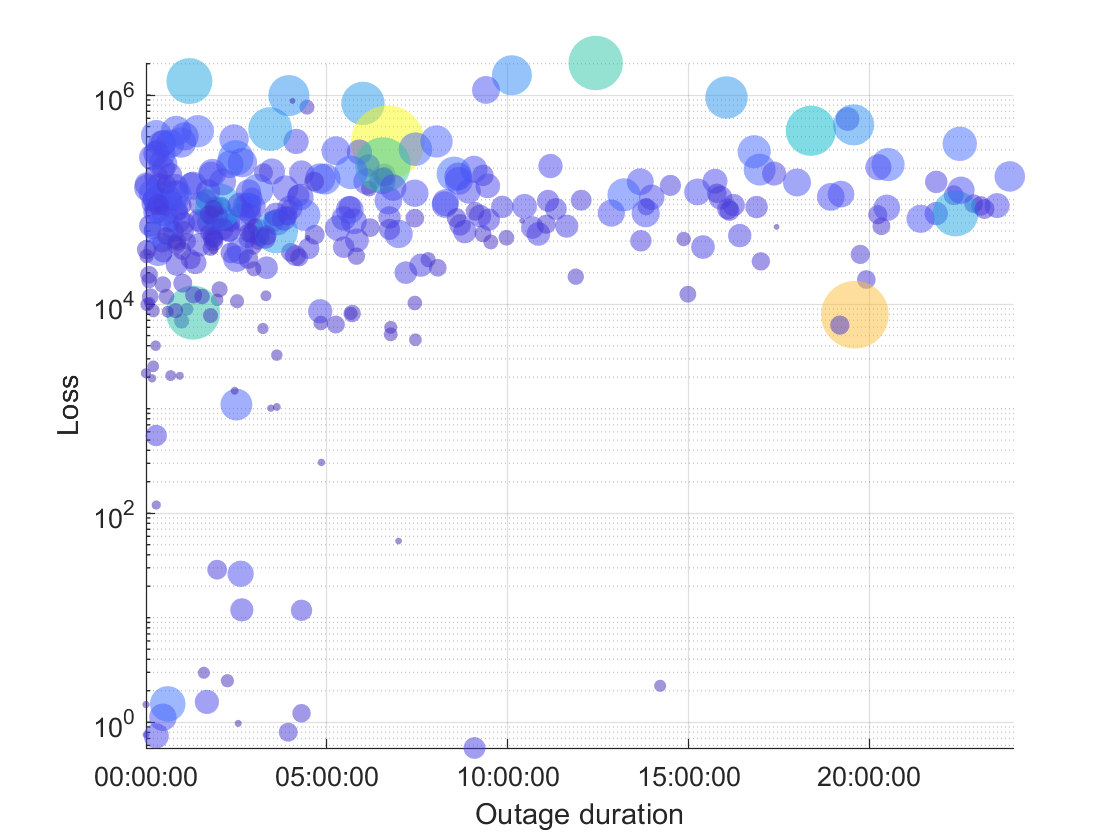

T = readtable('outages.csv');
scatter(T.RestorationTime - T.OutageTime, ...
    T.Customers, 5*sqrt(T.Loss+1), sqrt(T.Loss+1), ...
    "filled", "o", "MarkerFaceAlpha",0.5)
xlim([duration(0,0,0), duration(24,00,00)])
set(gca, "YScale", "log")
xlabel("Outage duration")
ylabel("Loss")
grid on
exportgraphics(gca, "outages.png")